# Call Python from MATLAB

**Goal:** Use Python code to import current weather data from the web. Predict air quality using MATLAB machine learning model.

## 1.Check that MATLAB can recognize the Python installation

Use `pyversion` if you are using a MATLAB version prior to R2019b.

pyenv(Version="C:\Users\KantikaWongkasem\AppData\Local\Programs\Python\Python311\python.exe ")

ans =   PythonEnvironment with properties:

          Version: "3.11"
       Executable: "C:\Users\KantikaWongkasem\AppData\Local\Programs\Python\Python311\python.EXE"
          Library: "C:\Users\KantikaWongkasem\AppData\Local\Programs\Python\Python311\python311.dll"
             Home: "C:\Users\KantikaWongkasem\AppData\Local\Programs\Python\Python311"
           Status: Loaded
    ExecutionMode: InProcess
        ProcessID: "22428"
      ProcessName: "MATLAB"


for windows OS to check Location

!where python

C:\Users\KantikaWongkasem\AppData\Local\Programs\Python\Python311\python.exe 


## 2.Run Python Code Live Task for 2024b

% Python code input
pycode = [...
"import pandas as pd",...
"# create a two-dimensional list",...
"data = [['John', 25, 'New York'],",...
"       ['Alice', 30, 'London'],",...
"       ['Bob', 35, 'Paris']]",...
"# create a DataFrame from the list",...
"df = pd.DataFrame(data, columns=['Name', 'Age', 'City'])",...
"print(df)"...
];

try
    [data2, df] = pyrun(pycode, ...
         [ "data" "df" ])
catch ME
    % Clear temporary variables from workspace and from Python
    clear pycode;
    rethrow(ME)
end

    Name  Age      City
0   John   25  New York
1  Alice   30    London
2    Bob   35     Paris


data2 =   Python list with values:

    [['John', 25, 'New York'], ['Alice', 30, 'London'], ['Bob', 35, 'Paris']]

    Use string, double or cell function to convert to a MATLAB array.


df =   Python DataFrame with properties:

          T: [1×1 py.pandas.core.frame.DataFrame]
         at: [1×1 py.pandas.core.indexing._AtIndexer]
      attrs: [1×1 py.dict]
       axes: [1×2 py.list]
    columns: [1×1 py.pandas.core.indexes.base.Index]
     dtypes: [1×1 py.pandas.core.series.Series]
      empty: 0
      flags: [1×1 py.pandas.core.flags.Flags]
        iat: [1×1 py.pandas.core.indexing._iAtIndexer]
       iloc: [1×1 py.pandas.core.indexing._iLocIndexer]
      index: [1×1 py.pandas.core.indexes.range.RangeIndex]
        loc: [1×1 py.pandas.core.indexing._LocIndexer]
       ndim: [1×1 py.int]
      shape: [1×2 py.tuple]
       size: [1×1 py.int]
     values: [1×1 py.numpy.ndarray]

        Name  Age      City
    0   John   25  New York
    1  Alice   30    London
    2    Bob   35     Paris



% Clear temporary variables from workspace and from Python
clear pycode;

Test a simple function.

py.math.sqrt(42)

ans = 6.4807

Use MATLAB name=value syntax for Python named arguments.

Pass arguments using pyargs.

%hw = py.textwrap.wrap("Hello world!",pyargs('width',2))   % errors
hw = py.textwrap.wrap("Hello world!",pyargs('width',int8(2)))

hw =   Python list with values:

    ['He', 'll', 'o ', 'wo', 'rl', 'd!']

    Use string, double or cell function to convert to a MATLAB array.


Convert to appropriate MATLAB type, if desired

hw = string(hw)

hw = 1×6 string array
    "He"    "ll"    "o "    "wo"    "rl"    "d!"


## 3.Read weather data using Python module 

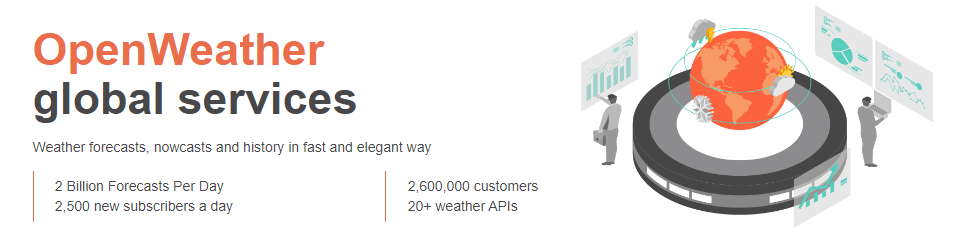

The weather.py module reads and parses current weather data from the web API: [https://openweathermap.org/api](https://openweathermap.org/api)

First, get the access key for the weather API.

apikey = readtable("accessKey.txt","TextType","string"); 

Use the weather.py module to get the air quality for Boston. This is a user-defined Python module which includes functions to read and parse the current and forecasted weather data by location.

jsonData = py.weather.get_current_weather("London","UK",apikey.Key)

jsonData =   Python dict with no properties.

    {'coord': {'lon': -0.1257, 'lat': 51.5085}, 'weather': [{'id': 804, 'main': 'Clouds', 'description': 'overcast clouds', 'icon': '04n'}], 'base': 'stations', 'main': {'temp': 32.86, 'feels_like': 32.86, 'temp_min': 30.29, 'temp_max': 35.1, 'pressure': 1027, 'humidity': 94, 'sea_level': 1027, 'grnd_level': 1024}, 'visibility': 10000, 'wind': {'speed': 2.3, 'deg': 210}, 'clouds': {'all': 99}, 'dt': 1732778525, 'sys': {'type': 2, 'id': 2075535, 'country': 'GB', 'sunrise': 1732779612, 'sunset': 1732809441}, 'timezone': 0, 'id': 2643743, 'name': 'London', 'cod': 200}


Parse the json data returned from the weather API.

weatherData = py.weather.parse_current_json(jsonData)

weatherData =   Python dict with no properties.

    {'temp': 32.86, 'feels_like': 32.86, 'temp_min': 30.29, 'temp_max': 35.1, 'pressure': 1027.0, 'humidity': 94.0, 'sea_level': 1027, 'grnd_level': 1024, 'speed': 2.3, 'deg': 210.0, 'lon': -0.1257, 'lat': 51.5085, 'city': 'London', 'current_time': '2024-11-28 14:23:10.004036'}


## 4.Preprocess data 

The **Python dictionary** can be represented as a **MATLAB struct**.

data = struct(weatherData)

data = struct with fields:
            temp: 32.8600
      feels_like: 32.8600
        temp_min: 30.2900
        temp_max: 35.1000
        pressure: 1027
        humidity: 94
       sea_level: [1×1 py.int]
      grnd_level: [1×1 py.int]
           speed: 2.3000
             deg: 210
             lon: -0.1257
             lat: 51.5085
            city: [1×6 py.str]
    current_time: [1×26 py.str]


Convert the remaining python types to the desired MATLAB data types.

string(data.city)

ans = "London"

Perform the remaining conversions using the function below. 

convertData(data)

ans = 1×12 table
      T        P       RH     WindSpd    WindDir    grnd_level    speed    deg      lon       lat        city           DateLocal      
    _____    _____    ____    _______    _______    __________    _____    ___    _______    ______    ________    ____________________

    32.86    32.86    1027      94        1027      1×1 py.int     2.3     210    -0.1257    51.508    "London"    28-Nov-2024 14:23:10


## 5.Handle timeseries with the weather forecast

Now let's look at the weather forecast for this week in Boston!

jsonData = py.weather.get_forecast("London","UK",apikey.Key);
% forecastData = py.weather.parse_forecast_json(jsonData);
forecastData = py.weather.parse_forecast(jsonData); % returns arrays instead of lists 
forecast = struct(forecastData)

forecast = struct with fields:
    current_time: [1×40 py.list]
            temp: [1×40 py.array.array]
             deg: [1×40 py.array.array]
           speed: [1×40 py.array.array]
        humidity: [1×40 py.array.array]
        pressure: [1×40 py.array.array]


The type of data returned by the parsed forecast date is a **Python array**:

forecast.temp

ans =   Python array:

   34.7500   39.3400   42.6600   40.1400   39.5800   40.5000   41.0900   41.9700   43.2900   48.0700   47.3000   45.0100   44.6500   45.8400   44.5800   44.4600   46.6300   51.6200   52.4500   49.8000   48.4200   47.6100   48.0600   49.1400   50.0700   53.1700   52.7400   52.5400   53.6400   53.8900   50.6700   49.4600   49.4600   50.0700   47.7000   45.5500   43.6500   43.5400   42.3900   40.2100

    Use details function to view the properties of the Python object.

    Use single function to convert to a MATLAB array.


It can be converted to a matrix of doubles:

tempForecast = double(forecast.temp)

tempForecast =    34.7500   39.3400   42.6600   40.1400   39.5800   40.5000   41.0900   41.9700   43.2900   48.0700   47.3000   45.0100   44.6500   45.8400   44.5800   44.4600   46.6300   51.6200   52.4500   49.8000   48.4200   47.6100   48.0600   49.1400   50.0700   53.1700   52.7400   52.5400   53.6400   53.8900   50.6700   49.4600   49.4600   50.0700   47.7000   45.5500   43.6500   43.5400   42.3900   40.2100


Transform **timestamp list** from Python in **MATLAB datetime**:

foreTime = cell(forecast.current_time)

foreTime = 1×40 cell array
    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}


T = cellfun(@string,foreTime)

T = 1×40 string array
    "2024-11-28 09:00:00"    "2024-11-28 12:00:00"    "2024-11-28 15:00:00"    "2024-11-28 18:00:00"    "2024-11-28 21:00:00"    "2024-11-29 00:00:00"    "2024-11-29 03:00:00"    "2024-11-29 06:00:00"    "2024-11-29 09:00:00"    "2024-11-29 12:00:00"    "2024-11-29 15:00:00"    "2024-11-29 18:00:00"    "2024-11-29 21:00:00"    "2024-11-30 00:00:00"    "2024-11-30 03:00:00"    "2024-11-30 06:00:00"    "2024-11-30 09:00:00"    "2024-11-30 12:00:00"    "2024-11-30 15:00:00"    "2024-11-30 18:00:00"    "2024-11-30 21:00:00"    "2024-12-01 00:00:00"    "2024-12-01 03:00:00"    "2024-12-01 06:00:00"    "2024-12-01 09:00:00"    "2024-12-01 12:00:00"    "2024-12-01 15:00:00"    "2024-12-01 18:00:00"    "2024-12-01 21:00:00"    "2024-12-02 00:00:00"    "2024-12-02 03:00:00"    "2024-12-02 06:00:00"    "2024-12-02 09:00:00"    "2024-12-02 12:00:00"    "2024-12-02 15:00:00"    "2024-12-02 18:00:00"    "2024-12-02 21:00:00"    "2024-12-03 00:00:00"    "2024-12-03 03:00:00"   

Convert T in datetime

time = datetime(T)

time = 1×40 datetime array
   28-Nov-2024 09:00:00   28-Nov-2024 12:00:00   28-Nov-2024 15:00:00   28-Nov-2024 18:00:00   28-Nov-2024 21:00:00   29-Nov-2024 00:00:00   29-Nov-2024 03:00:00   29-Nov-2024 06:00:00   29-Nov-2024 09:00:00   29-Nov-2024 12:00:00   29-Nov-2024 15:00:00   29-Nov-2024 18:00:00   29-Nov-2024 21:00:00   30-Nov-2024 00:00:00   30-Nov-2024 03:00:00   30-Nov-2024 06:00:00   30-Nov-2024 09:00:00   30-Nov-2024 12:00:00   30-Nov-2024 15:00:00   30-Nov-2024 18:00:00   30-Nov-2024 21:00:00   01-Dec-2024 00:00:00   01-Dec-2024 03:00:00   01-Dec-2024 06:00:00   01-Dec-2024 09:00:00   01-Dec-2024 12:00:00   01-Dec-2024 15:00:00   01-Dec-2024 18:00:00   01-Dec-2024 21:00:00   02-Dec-2024 00:00:00   02-Dec-2024 03:00:00   02-Dec-2024 06:00:00   02-Dec-2024 09:00:00   02-Dec-2024 12:00:00   02-Dec-2024 15:00:00   02-Dec-2024 18:00:00   02-Dec-2024 21:00:00   03-Dec-2024 00:00:00   03-Dec-2024 03:00:00   03-Dec-2024 06:00:00


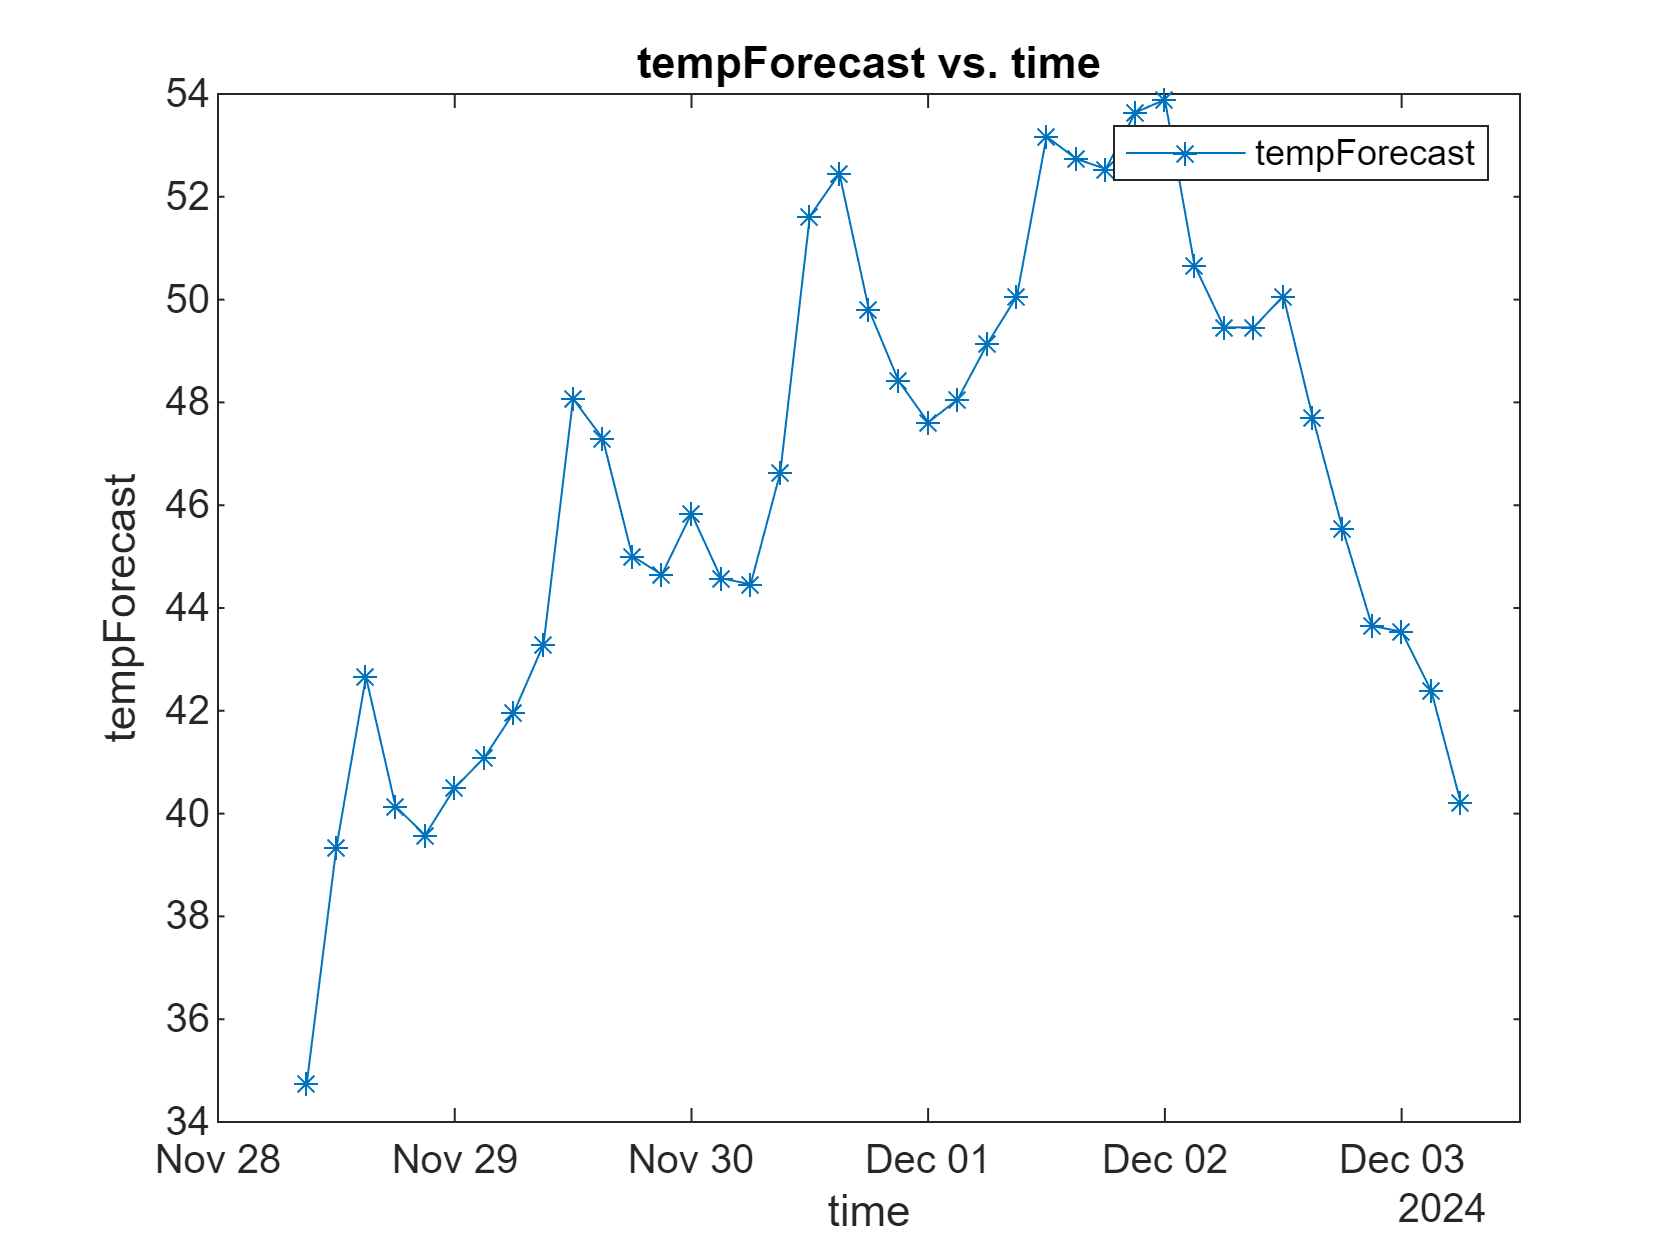

% Create plot of time and tempForecast
h = plot(time,tempForecast,"Marker","*","DisplayName","tempForecast");

% Add xlabel, ylabel, title, and legend
xlabel("time")
ylabel("tempForecast")
title("tempForecast vs. time")
legend

plot(time,tempForecast,'-*')
%xtickangle(45)

## 6.Preprocess data using MATLAB live task

Weather forecasts are only provided every 4 hours. We want to retime to have data interpolated every single hour.

foreTemp = timetable(time',tempForecast','VariableNames',{'Temperature'})

foreTemp = 40×1 timetable
            Time            Temperature
    ____________________    ___________

    28-Nov-2024 09:00:00       34.75   
    28-Nov-2024 12:00:00       39.34   
    28-Nov-2024 15:00:00       42.66   
    28-Nov-2024 18:00:00       40.14   
    28-Nov-2024 21:00:00       39.58   
    29-Nov-2024 00:00:00        40.5   
    29-Nov-2024 03:00:00       41.09   
    29-Nov-2024 06:00:00       41.97   
    29-Nov-2024 09:00:00       43.29   
    29-Nov-2024 12:00:00       48.07   
    29-Nov-2024 15:00:00        47.3   
    29-Nov-2024 18:00:00       45.01   
    29-Nov-2024 21:00:00       44.65   
    30-Nov-2024 00:00:00       45.84   
    30-Nov-2024 03:

***Retime TimeTable*** from 2 hours to 1 hour

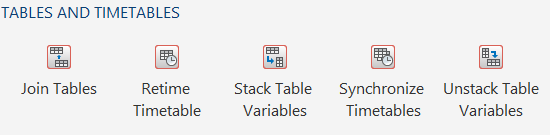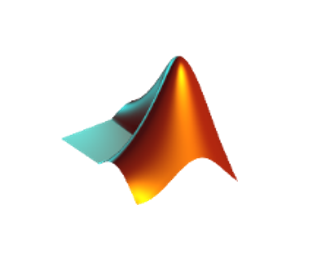

% Retime timetable
newTimetable = retime(foreTemp,"regular","linear","TimeStep",hours(1))

newTimetable = 118×1 timetable
            Time            Temperature
    ____________________    ___________

    28-Nov-2024 09:00:00       34.75   
    28-Nov-2024 10:00:00       36.28   
    28-Nov-2024 11:00:00       37.81   
    28-Nov-2024 12:00:00       39.34   
    28-Nov-2024 13:00:00      40.447   
    28-Nov-2024 14:00:00      41.553   
    28-Nov-2024 15:00:00       42.66   
    28-Nov-2024 16:00:00       41.82   
    28-Nov-2024 17:00:00       40.98   
    28-Nov-2024 18:00:00       40.14   
    28-Nov-2024 19:00:00      39.953   
    28-Nov-2024 20:00:00      39.767   
    28-Nov-2024 21:00:00       39.58   
    28-Nov-2024 22:00:00      39.887   
    28-Nov-202

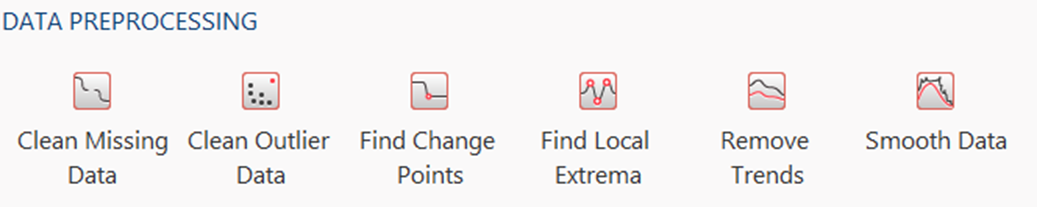

***Clean Data with Live Task***

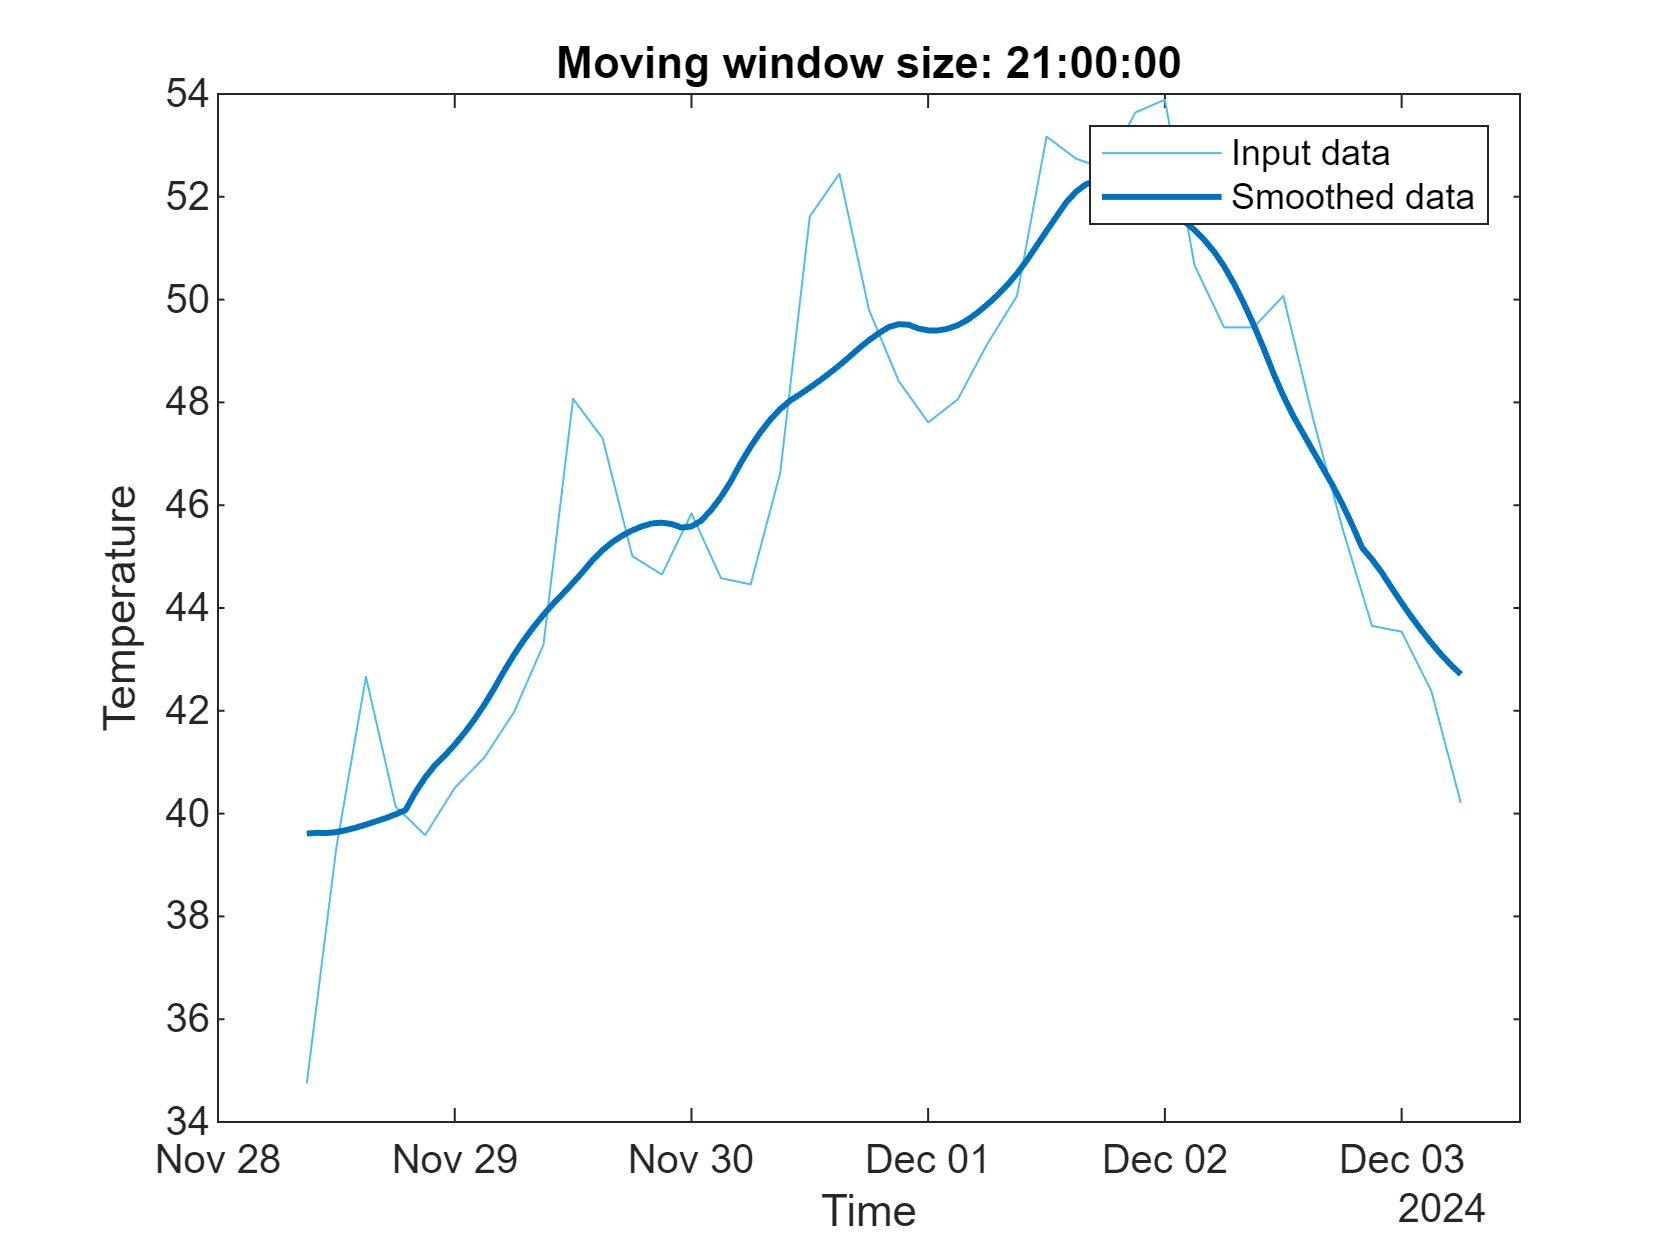

% Smooth input data
[newTable,winSize] = smoothdata(newTimetable,"movmean","SmoothingFactor",0.25);

% Display results
figure
plot(newTimetable.Time,newTimetable.Temperature,"SeriesIndex",6, ...
    "DisplayName","Input data")
hold on
plot(newTimetable.Time,newTable.Temperature,"SeriesIndex",1,"LineWidth",1.5, ...
    "DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize));
legend
ylabel("Temperature")
xlabel("Time")

clear winSize

## 7.Predict air quality

The machine learning model has been trained and validated on a large amount of historical climate data. The model is then saved as a .mat file for use in production. 

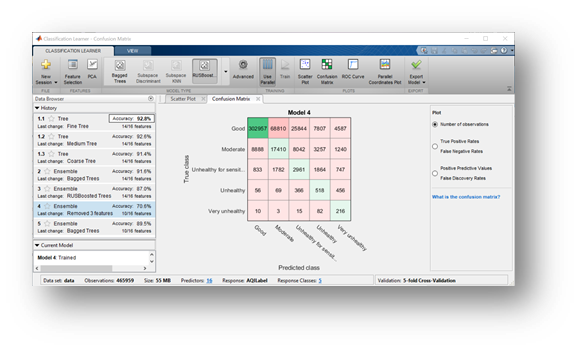

Use a function (`prepData.m`) to convert and prepare data for machine learning (create a table with the expected variable names, preprocessing steps, etc). 

currentData = prepData(weatherData)

Use the model to predict the air quality for the new weather data.

'*airQualModel.mat*' is a pre-trained Bagged Classification Tree/ "Random Forest" classification network. The network was trained using a large data set stored on a local HDFS cluster (~1TB of historical weather data) and required the use of the "tall" MATLAB datatype.  The model was saved as a *.mat file for use in predicting air quality in this demonstration. 

load airQualModel 

airQual = predict(model,currentData)

## Share prediction code

Create a function with these steps to be called in the Python environment.

edit("predictAirQual.m")

See `CallMATLABfromPython.ipynb`

## Reload Python module

Reload *weather.py *after modifications:

clear classes
mod = py.importlib.import_module('weather'); 
py.importlib.reload(mod);

Read the documentation to know more:

[Reload Modified User-Defined Python Module - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/releases/R2015b/matlab/matlab_external/call-modified-python-module.html)

**Helper Functions**

function data = convertData(data)
% Organize and convert data types 
data = struct2table(data);
% Check for wind direction (deg), sometimes missing
if ~any(data.Properties.VariableNames == "deg")
    deg = "";
    data = addvars(data,deg,'After','speed');
end
data = removevars(data,["temp_min","temp_max"]);
data.Properties.VariableNames([1:5,end]) = ["T","P","RH","WindSpd","WindDir","DateLocal"];
data = convertvars(data,["T","P","RH","WindSpd","WindDir"],"double");
data = convertvars(data,["city","DateLocal"],"string");

% Convert date
if strlength(data.DateLocal) > 20
    data.DateLocal = datetime(data.DateLocal,"InputFormat","uuuu-MM-dd HH:mm:ss.SSS");
else
    data.DateLocal = datetime(data.DateLocal);
end

end

*Copyright 2018-2021 The MathWorks, Inc.*